## Principal Component Analysis

load('omni.mat'); % images{i}.img
nIms = 550; nRows = 112; nCols = 150; nFeat = nRows * nCols;
nTrain = 300; nTest = nIms - nTrain;
% Create column vectors, subtract mean
X = zeros(nFeat, nTrain);
for i = 1:nIms
    img = images{i}.img;
    img = 1 / sum(sum(img)) * img;
    img = reshape(img, [nFeat, 1]);
    X(:, i) = img;
end
XMean = mean(X');
X0 = (X' - XMean)';
% Split into train and test
XTrain = X0(:,1:nTrain); XTest = X0(:,nTrain+1:nIms);
YTrainMean = XMean';
YTestMean = XMean';

% We want the k largest eigenvectors of the 
% covariance matrix, Q = X X^T. 
tic;
k = 50;

% Correlation matrix method:
% Q = XTrain * XTrain';
% [eVecs, eVals] = eigs(Q, k); 

% SVD method:
[eVecs, eVals, V] = svd(XTrain, 'econ');
eVals = eVals(:, 1:k).*eVals(:, 1:k);
eVecs = eVecs(:, 1:k);
oneTimeCost = toc;

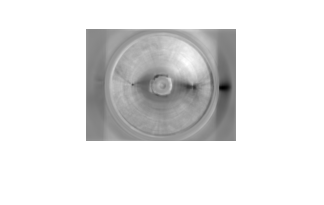

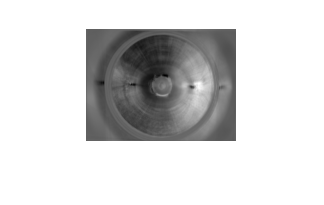

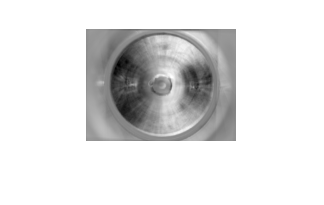

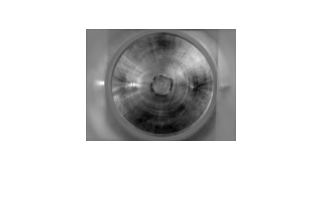

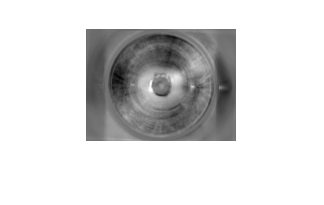

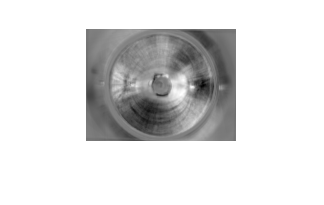

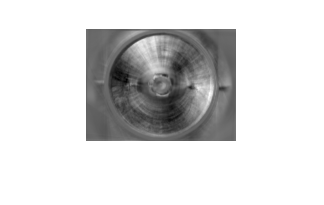

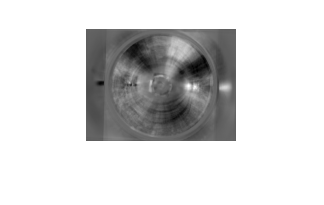

% Showing 9 most principal components
clf;
for i = 1:9
    figure;
    eImage = reshape(eVecs(:, i), [nRows, nCols]);
    imshow(eImage, []);
end

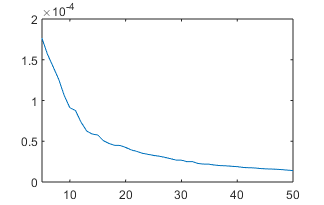

% Plotting the 'principality' of the k components
deVals = diag(eVals);
plot(deVals); 
xlim([5 k]); % largest few make the rest look like 0

% We could probably set k to 20, but it's fast enough @ 50
% k = 20;
% eVecs = eVecs(:, 1:k);

% Now let's try expressing images in terms of this 50-/k-sized basis.
gTrain = eVecs' * XTrain;
YTrain = gTrain' * eVecs';
YTrain = YTrain'+ YTrainMean; % to match the 'image per column' of Xtrain
% That feels circular  but our results are too bad for that.
i = 10;
reshape(YTrain(:,i), [nRows, nCols]);
reshape(X0(:,i), [nRows, nCols]);
% Test set, should be worse.
gTest = eVecs' * XTest;
YTest = gTest' * eVecs';
YTest = YTest' + YTestMean;
recIm = reshape(YTest(:, i), [nRows, nCols]);
actIm = reshape(X0(:, i+nTrain), [nRows, nCols]);

% By g lookup. 
error1 = 0; error2 = 0; good1 = 0; good2 = 0;
T = 1000;
% gTrain is our database, want the actual image to be from test.
tic;
for t = 1:T
    % Get and prep an image.
    actualJ = round((nTest-1).*rand(1,1) + 1) + nTrain;
    refImRaw = images{actualJ}.img;
    % Do the same stuff as for X initially.
    i = 1 / sum(sum(refImRaw)) * refImRaw; 
    i = reshape(i, [nFeat, 1]);
    i = i - XMean(:,1);
    % Find eigenspace coordinates.
    g = eVecs' * i;
    % Look in database, update lowest Euclidean distance.
    bestJ = 0; bestD = 9001;
    for j = 1:nTrain
        d = norm(g(:) - gTrain(:, j));
        if (d < bestD)
            bestJ = j;
            bestD = d;
        end
    end 
    thisIm = X0(:, bestJ);
    thisIm = reshape(thisIm, [nRows, nCols]);
    refIm = X0(:, actualJ);
    refIm = reshape(refIm, [nRows, nCols]);
    error1 = error1 + norm(refIm - thisIm); 
    if (actualJ == bestJ)
        good1 = good1 + 1;
    end
end
t1 = toc;
% Showing last combo
bestD

bestD = 0.0034

norm(refIm - reshape(X0(:, 42), [nRows, nCols])) % dist to random

ans = 0.0031

norm(refIm - thisIm)

ans = 0.0016

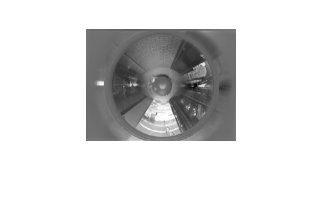

imshow(thisIm, []);

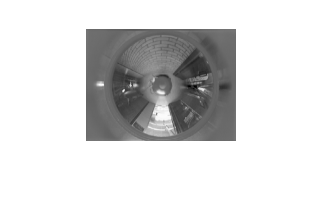

imshow(refIm,[]);

tic;
for t = 1:T
    actualJ = round((nTest-1).*rand(1,1) + 1) + nTrain;
    refIm = images{actualJ}.img;
    bestJ = 0; bestD = 9001; %actualD = norm(g(:) - gTest(:, actualJ));
    for j = 1:nTrain
        d = norm(refIm(:) - X0(:, j));
        if (d < bestD)
            bestJ = j;
            bestD = d;
        end
    end
    thisIm = X0(:, bestJ);
    thisIm = reshape(thisIm, [nRows, nCols]);
    refIm = X0(:, actualJ);
    refIm = reshape(refIm, [nRows, nCols]);
    error2 = error2 + norm(refIm - thisIm);
    if (actualJ == bestJ)
        good2 = good2 + 1;
    end
end
t2 = toc;
% Showing last combo
norm(refIm - thisIm)

ans = 0.0017

norm(refIm - reshape(X0(:, 42), [nRows, nCols])) % dist to random

ans = 0.0031

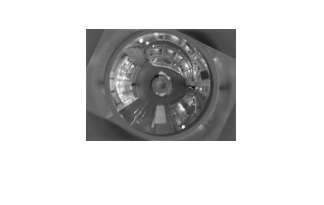

imshow(thisIm,[]);

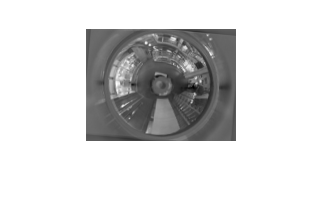

imshow(refIm,[]);

t2/t1*100 % speed of PCA in % of naive image comparison

ans = 601.8544

t2/(t1+oneTimeCost)*100 % including one-time cost of finding cov eigs

ans = 560.5044

error2/error1*100 % relative accuracy in %

ans = 145.0072

good1/T*100 % absolute accuracy of PCA

ans = 0

good2/t*100 % absolute accuracy of comparison

ans = 0

% And these should be 0 as long as we compare test images to a database
% made up of training images.

## Positioning with Nearest Neighbour

% We've already made our gTest and yTest and such above. That's
% most of those 40 points probably. A copy-paste:
gTrain = eVecs' * XTrain;
YTrain = gTrain' * eVecs';
YTrain = YTrain'+ YTrainMean; 
gTest = eVecs' * XTest;
YTest = gTest' * eVecs';
YTest = YTest' + YTestMean;

% And we already have the normed distance in our loop above, only
% that's for a random image instead of for all. What we now have to
% do is, for every test image, find bestJ/bestD in gTrain(:,j). 
correct = 0;
for t = 1:nTest
    % Get and prep the current Ytest image.
    refIm = reshape(YTest(:, t), [nRows, nCols]);
    % Do the same stuff as for X initially.
    i = 1 / sum(refIm(:)) * refIm; 
    i = reshape(i, [nFeat, 1]);
    i = i - XMean(:,1);
    % Find eigenspace coordinates.
    g = eVecs' * i;
    % Look in database, update lowest Euclidean distance.
    bestJ = 0; bestD = 9001;
    for j = 1:nTrain
        d = norm(g(:) - gTrain(:, j));
        if (d < bestD)
            bestJ = j;
            bestD = d;
        end
    end
    % Find the distance between the position of the best match and the actual position and check if it is close enough
    distance = norm(images{bestJ}.position-images{t+nTrain}.position);
    if (distance < 150)
        correct = correct + 1;
    end
end
accuracy = correct / nTest * 100

accuracy = 67.6000

Removing the borders of the images would make no difference in the accuracy, since all borders are of the same color and on the exact same location, which means that the variance of the borders between images is 0. Because of this, the borders will be in one of the lowest dimensions of k and most likely isn't one of the eigenvectors that is compared between images. This means that the borders have no influence on the comparison process between images (unless the dimensions aren't reduced), which means that removing them makes no difference in the results.

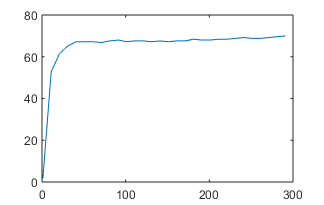

klist = 1:10:300;
count = 0;
for k = klist
    tic
    [eVecs, eVals, V] = svd(XTrain, 'econ');
    eVals = eVals(:, 1:k).*eVals(:, 1:k);
    eVecs = eVecs(:, 1:k);    gTrain = eVecs' * XTrain;
    YTrain = gTrain' * eVecs';
    YTrain = YTrain'+ YTrainMean;
    gTest = eVecs' * XTest;
    YTest = gTest' * eVecs';
    YTest = YTest' + YTestMean;
    correct = 0;
    for t = 1:nTest
        % Get and prep the current Ytest image.
        refIm = reshape(YTest(:, t), [nRows, nCols]);
        % Do the same stuff as for X initially.
        i = 1 / sum(refIm(:)) * refIm; 
        i = reshape(i, [nFeat, 1]);
        i = i - XMean(:,1);
        % Find eigenspace coordinates.
        g = eVecs' * i;
        % Look in database, update lowest Euclidean distance.
        bestJ = 0; bestD = 9001;
        for j = 1:nTrain
            d = norm(g(:) - gTrain(:, j));
            if (d < bestD)
                bestJ = j;
                bestD = d;
            end
        end
        % Find the distance between the position of the best match and the actual position and check if it is close enough
        distance = norm(images{bestJ}.position-images{t+nTrain}.position);
        if (distance < 150)
            correct = correct + 1;
        end
    end
    % Calculate the accuracy and stop the timer and add it to the accuracy vector / time vector respectively
    count = count + 1;
    accuracy(count) = correct / nTest * 100;
    timevector(count) = toc;
end
plot(klist, accuracy)

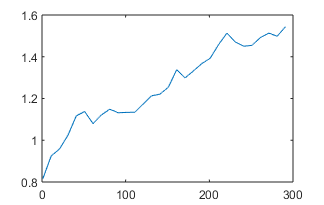

plot(klist, timevector)

With only a few components used, the accuracy is really low, but the accuracy increases rapidly once more components are added, and once there are about 30 components, the accuracy is pretty good (around 64%). By using more than 30 components, the accuracy will increase slightly at the cost of a slower processing speed and a higher memory cost. If a higher memory cost and slower processing speed isn't relevant, an accuracy of 70% can be reached by using all 300 components, which is slightly better than the 64% accuracy obtained by using 30 components. 

Good choices for the value of k (the amount of components used) are:

- 30, which results in a 64% accuracy which is pretty high for how few components are used, which means that it is fast to compute (it takes around 3 seconds)

- 300, which results in a 70% accuracy, which is the most accurate PCA you can get. This takes the longest to compute, however (it takes around 5 seconds).

- 100, which results in a 67.2% accuracy, which is a great inbetween since it is a lot faster than using 300 (it takes around 4 seconds), while being quite a bit more accurate than 30. This is also around the point where the accuracy decrease really starts to slow down.

correct = 0;
tic
for t = 1:nTest
    % Get and prep the current Ytest image.
    refIm = reshape(YTest(:, t), [nRows, nCols]);
    bestJ = 0; bestD = 9001; %actualD = norm(g(:) - gTest(:, actualJ));
    for j = 1:nTrain
        d = norm(refIm(:) - X0(:, j));
        if (d < bestD)
            bestJ = j;
            bestD = d;
        end
    end
    % Find the distance between the position of the best match and the actual position and check if it is close enough
    distance = norm(images{bestJ}.position-images{t+nTrain}.position);
    if (distance < 150)
        correct = correct + 1;
    end
end
correct / nTest * 100

ans = 70

toc

Elapsed time is 4.970419 seconds.


Using the Nearest Neighbour algorithm instead of PCA, an accuracy of 70% is reached, which is the same accuracy score that PCA manages to get with all 300 components in use. While it is pretty slow, it does work just as good as PCA can be at is best on the front of accuracy, which makes sense, since the main reason we use PCA isn't because it will return us a higher accuracy, but because we can choose to reduce the amount of components, which can give us a significant speedup, while not losing that much accuracy.

The curse of dimensionality causes it to be a lot slower, but not slow enough for it to become unusuable. Compared to PCA, however, the NN algorithm takes forever, since even when using all of the PCA component, the PCA is still more than  twice as fast while having the same accuracy.